storage part

% clear;
s = 13; %total # of nodes
x = 1; %# of r_i
y = 1; %# of c_i
z = 1; %# of c_{i+1}
lambda = 2453.7*2/s/(s-1);
Lambda = 100;
% tempRatio = 1;
smplIntrv = 60;
 cutoff = 4800;

path = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\apr2018\CONVEN\n7-CON-cs4k-pit', num2str(cutoff), '-cl6k-rr'];
% path = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\apr2018\CONVEN\n5-CON-cs4k-pit', '6k', '-cl6k-rr'];
% pre = '1k';
file1 = '-app-time-name.txt';
file2 = '-app-time-num.txt';
file3 = '-app-name-delay.txt';



% AAP trans storage matrix initialization
[preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n ] = assVar( s, x, y, z  );
[preTransSto, req_n, cont_n]= twoContent(s,x,y,z, preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n);

% conventional trans storage matrix initialization
[conTransSto, N, VStep, MStep, conReq_n, conCont_n] = genTransMatrixSto(s, x, y, z, lambda);
conCont_n = conCont_n +1;
toCont = [2, 1];
indexsum = cumsum(0:(s-2));


pre = num2str(Lambda);
% pre = '1.5k';
% [path, pre, file2]
rawdat = importdata([path, pre, file2]);

esto = rawdat.data;
rawdat = importdata([path, pre, file1]);
esto = [esto rawdat.data(:,2)];
% esto=[];
rawdat = importdata([path, pre, file3]);
cdelay = rawdat.data(:,2);

testSize = ceil(Lambda/lambda);

% conventional initial dist initialization
conInit = zeros(1,size(conTransSto,1));
conInit(1) = 1;

% AAP initial dist initialization
preInit = zeros(1,size(preTransSto,1));
% init(twoContentTrPos(1,1,1, transitPos, absorbPos )) = 1;

state01 = 0;

for k = 1:5
    %simulation
    [~, conBinVal,   conFin]  = delayPDFsto(conTransSto,    conInit, testSize, conCont_n,  lambda);
    [~, binVal2,     preFin]  = delayPDFsto(preTransSto,    preInit, testSize, cont_n(2,:)', lambda);
    [t, binVal1 ]             = delayPDFsto(preTransSto,    preInit, testSize, cont_n(1,:)', lambda);

%     f = figure();
%     plot(preInit,'Displayname','init');
%     hold on;
%     plot(preFin,'Displayname', 'fin');
%     plot(state01,'Displayname', 'state01');
% 
%     plot(cont_n(2,:)/10, 'Displayname', 'b_i+1');
%     plot( (cont_n(2,:)+cont_n(1,:)) /10, 'Displayname', 'c_i');
%     legend('show');

%     temp = preFin*cont_n(2,:)' + conFin*(conCont_n);
    disp(sum(preFin)+sum(conFin)+sum(state01));
    [preInit, conInit, state01] = nextInit_v2(s, preTransSto, preFin, cont_n, transitPos, ...
        absorbPos, conTransSto, conFin, conCont_n, indexsum, state01);
    disp(sum(preInit)+sum(conInit)+sum(state01));
%     temp = temp - preInit'*(cont_n(2,:) + cont_n(2,:) )' - conFin*(conCont_n);
        
    preInit = preInit'; 
    conInit = conInit'; 
end

     1



     1



     1



     1



    1.0000



    1.0000



    1.0000



    1.0000



    1.0000



    1.0000



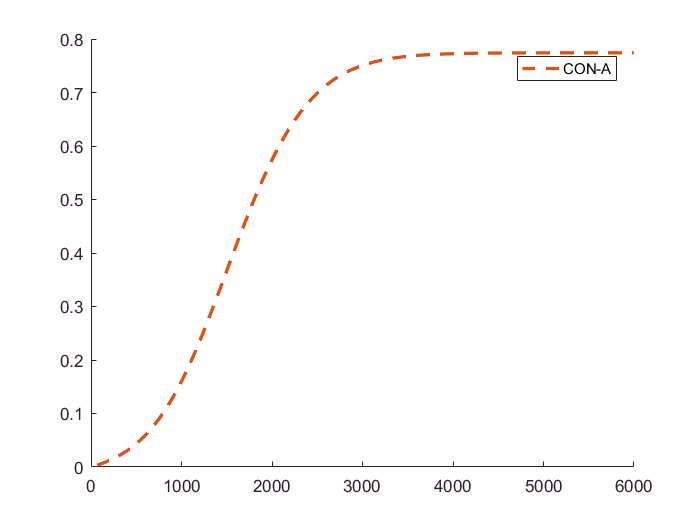


testSize = ceil( 6000/lambda);
[~, finConBinVal]  = delayPDFsto(conTransSto,   conInit, testSize, conCont_n,    lambda);
[~, finBinVal2]    = delayPDFsto(preTransSto,   preInit, testSize, cont_n(2,:)', lambda);
[fint, finBinVal1] = delayPDFsto(preTransSto,   preInit, testSize, cont_n(1,:)', lambda);
finS01 = ones(1,testSize-1)*state01;
% figure;
% % plot(t, binVal1/(s-1), 'DisplayName', 'ci');
% hold on; 
% plot(t, binVal2/(s-1), 'DisplayName', 'bi+1');
% plot(t, conBinVal/(s-1), 'DisplayName', 'con_i');

% hold off;

% figure;
% 
% combindedBin = [(binVal2+conBinVal) (finBinVal1 + finBinVal2 + finConBinVal+finS01)];
% plot([t fint+max(t)], (combindedBin-1)/(s-1),...
%     'DisplayName', 'AAP-A','LineWidth',1.5);
figure;hold on;
combindedBin = (finBinVal1 + finBinVal2 + finConBinVal+finS01);
% plot(fint, (combindedBin-1)/(s-1),...
%     'DisplayName', 'AAP-A','LineWidth',1.5, 'LineStyle', '-', 'Color', [0 0.45 0.74]);

% CON storage ratio 
conini = zeros(1,size(conTransSto,1));conini(1) = 1;
[t, conBinVal ] = delayPDFsto( conTransSto, conini, testSize, conCont_n, lambda);
plot(t,(conBinVal-1)/(s-1),'DisplayName', 'CON-A','LineWidth',2,'LineStyle','--', 'Color', [0.85 0.33 0.1]);
legend('show');

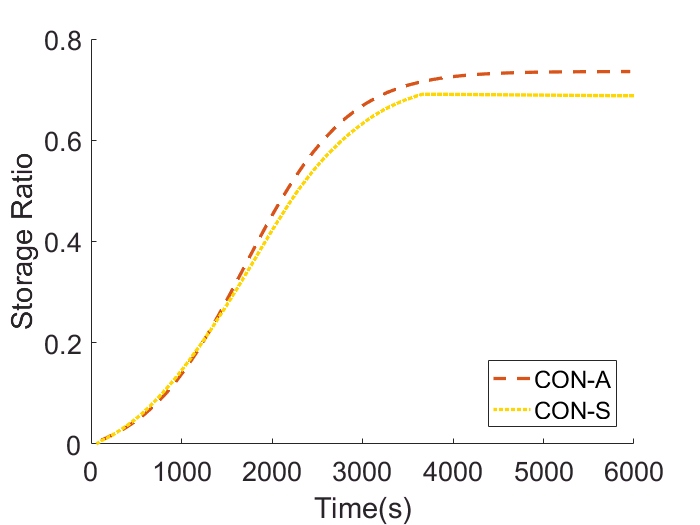

con_m = content_num_process(esto,smplIntrv);
econ = con_m/(s-1);
tmax = 1:ceil(max(t)/smplIntrv);
plot( (tmax)*smplIntrv , econ(tmax), 'DisplayName', 'CON-S','LineWidth',2,'LineStyle',':', 'Color', [1 0.84 0] );
legend('off');
legend('show','Location','southeast');
xlabel('Time(s)');
ylabel('Storage Ratio');
set(gca,'FontSize',16);

delay part

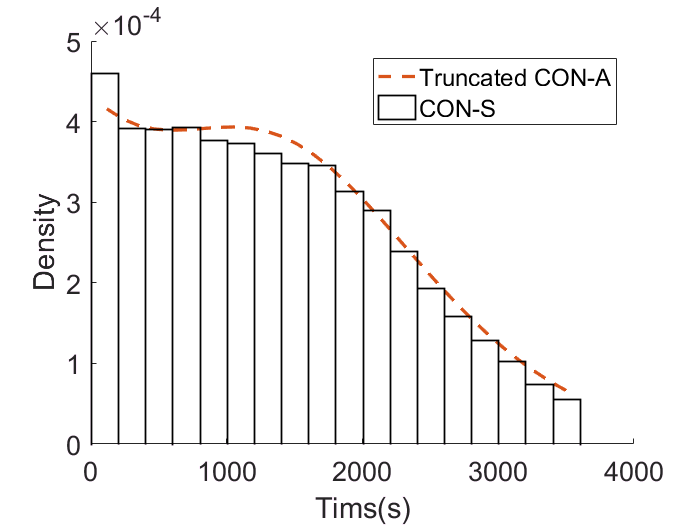


a = 1;b = 1; c = 1;  e = s*(s-1)/2;
test_size = ceil(6000/lambda);
[trans,~] = genTransMatrix(s, a, b, c, lambda);
cutoffb = ceil(cutoff/lambda);
figure; hold on;
% delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    
% [ggpdf, binVal ] = delayPDF_v3( trans, delayInit, test_size, e, lambda );
% plot((1:test_size-1)*lambda,ggpdf, 'DisplayName', 'AAP-A','LineWidth',1.5,'Color', [0 0.45 0.74]); 

ini = zeros(1,size(trans,1));ini(1) = 1;
[ggpdf, binVal ] = delayPDF_v3( trans, ini, test_size, e, lambda );
ggpdf = ggpdf /sum(ggpdf(1:(cutoffb-1))*lambda);
plot((1:(cutoffb-1))*lambda, ggpdf(1:(cutoffb-1)), 'DisplayName', 'Truncated CON-A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 
% plot((1:(test_size-1))*lambda, ggpdf, 'DisplayName', 'CON-A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 

ccdf = histogram(cdelay,'BinWidth',200,'Normalization','pdf','DisplayName','CON-S',...
    'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
xlabel('Tims(s)');
ylabel('Density');
legend('show');
set(gca,'FontSize',16)

% 
% pref_f = unique(pref_f);
% pref_delay = edelay(:,1)==pref_f(1);
% for i=2:size(pref_f)
%     pref_delay = pref_delay | edelay(:,1)==pref_f(i);
% end
% pref_delay=edelay(pref_delay,2);
% hold on;
% ecdf = histogram(pref_delay,'BinWidth',200,'Normalization','cdf');
% 
